# Getting Started with 4DNvestigator

## 4DNvestigator Overview

### What is the 4DNvestigator

The 4DNvestigator is a toolbox for analyzing time-series genome-wide chromosome conformation capture (Hi-C) and gene expression (RNA-seq) data.  This document outlines each of the core functions of the 4DNvestigator which can be run using **ExampleScript.m**.

### Initial Setup of 4DNvestigator Environment

The 4DNvestigator requires the following MATLAB Toolboxes:

- Statistics and Machine Learning Toolbox

- Computer Vision Toolbox

- Bioinformatics Toolbox

- Image Processing Toolbox

In **ExampleScript.m**, we first prepare the MATLAB environment:

close all, clear %%% Close figures and reset variables
restoredefaultpath %%% Ensure no other folders on current path
addpath(genpath(pwd)) %%% Add all 4DNvestigator folders and files to path

### Loading Processed Hi-C and RNA-seq Data

The 4DNvestigator accepts Hi-C data from Juicer (.hic) and RNA-seq data from RSEM (.genes.results). To input these data into MATLAB, the 4DNvestigator requires a metadata table, referred to as an “Index File”, to describe the data.  Rows correspond to sequencing data samples (RNA-seq or Hi-C), and the columns correspond to data descriptors. The Index File must have 5 columns with the following headers: 

- "path” defines the computer path to the sequencing data

- “dataType” defines the type of sequencing data, either “hic” or “rnaseq”

- “sample” defines the sample, (e.g.  “treatment” or “control”)

- “timePoint” defines the time point of sample, (e.g.  0 or 24)

- "refGenome" defines the reference genome for the sample (e.g. "hg19")

All example data and the example index file should be downloaded to the directory **data\exampleData\** from Google Drive: [4DNvestigator Example Data](https://drive.google.com/drive/folders/1xVjX7yqiOIPV_IfVKVDJJ79Ee0xMHGr8?usp=sharing). This data can be loaded using 4DNvestigator as shown below.

Index_Loc = 'data\exampleData\myodData\sampleMyodDataIndexTp-48_8_80.xlsx'; %%% Index file
Data_Loc = 'data\exampleData\myodData\'; %%% Data input

[dataInfo] = fdnLoadUserInput(Index_Loc); %%% Load index file
[H] = fdnLoadHic(Data_Loc,dataInfo,'single'); %%% Load Hi-C data
[R] = fdnLoadRnaseq(Data_Loc,dataInfo,H); %%% Load RNA-seq data

## Example Usage of the 4DNvestigator Tools

### Feature Analyzer

The Feature Analyzer takes in Hi-C and RNA-seq data (formatted as shown above) and computes the changes in structure and function between samples. For ease of use, a pre-formatted dataset from a cellular reprogramming experiment is used as an example [1].

The function **featureAnalyzerExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. The remaining parameters, **chrSelect**, **dimReduc**, and **binSize**, correspond to the chromosome used for analysis, the method of dimension reduction used for visulization (PCA = 'pca', Laplacian Eigenmaps = 'lapeigen', or t-SNE = 'tsne'), and the desired resolution of the data. The values assigned to these parameters shown below are the default if none are specified.

Data_Loc = 'data\exampleData\myodData\myodData.mat'; %%% Data input
Folder_Result = 'results\featureAnalyzerResults'; %%% Output folder
chrSelect = 11; 
dimReduc = 'pca';
binSize = 1E5;
featureAnalyzerExample(Data_Loc, Folder_Result, chrSelect, dimReduc, binSize)

Points in the figure below correspond to genomic loci (100 kb).  Loci that change the most in structure and function (top 10% of bins, default setting) are plotted, the top 10 loci are fit with red minimum volume ellipses, and genes within these regions are listed in the figure.

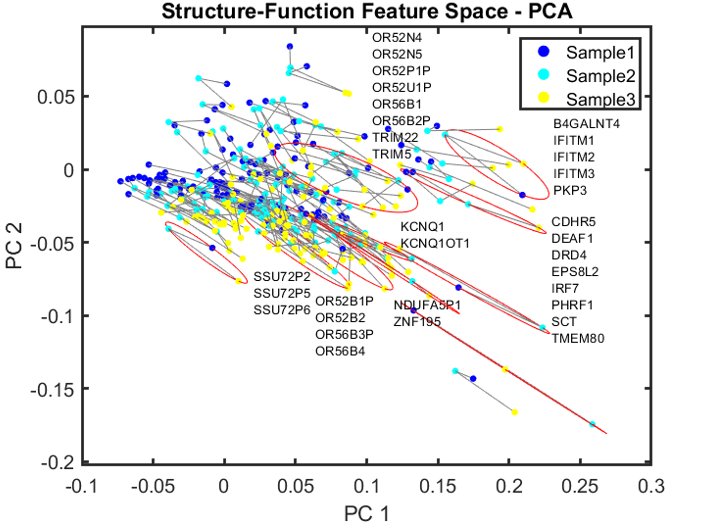

The Structure-Function Feature Space can also be visualized using non-linear dimension reduction techniques:

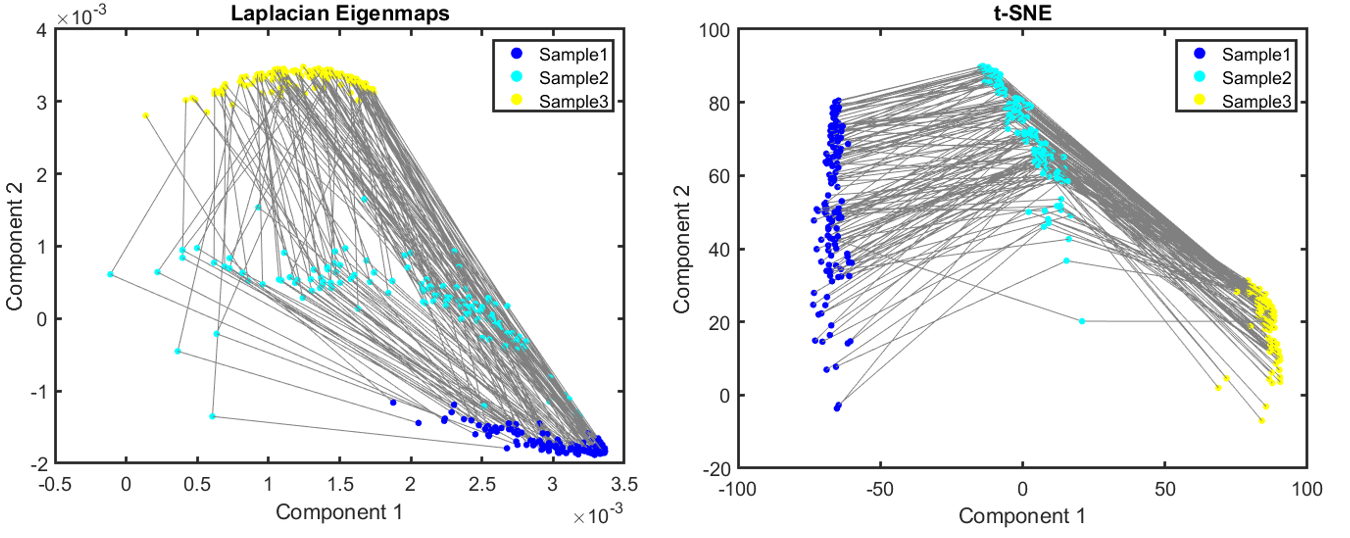

### Von Neumann Graph Entropy

#### Two Cell Types

Von Neumann Graph Entropy (VNE) is calculated for Hi-C data (formatted as shown above) and can be used to compare the entropy of multiple cell types. In this example, we show two cell types to highlight the differences in chromatin organization and their entropy [2, 3, 4].

The function **vneExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. The remaining parameters, **chrSelect**, **bpFrag**, and **binSize**, correspond to the chromosome used for analysis, the choice of coordinates (base pair = 'BP' or fragment = 'FRAG'), and the desired resolution of the data. The values assigned to these parameters shown below are the default if none are specified.

Data_Loc = {'data\exampleData\4DNFIFLJLIS5.hic',...
            'data\exampleData\4DNFIOX3BGNE.hic'}; %%% Data input
Folder_Result = 'results\vneExampleResults'; %%% Output folder
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExample(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize)

The VNE for an undifferentiated cell type (embryonic stem cell, H1-hESC) is much higher than the more differentiated cell type (fibroblast, HFFc6). Intra-chromosome log2(A) Hi-C matrices are shown at 100 kb resolution for chromosome 14.

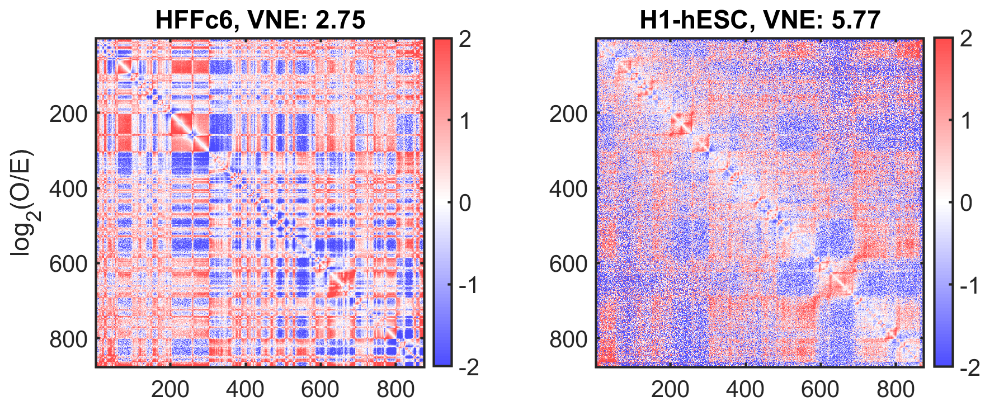

#### Many Cell Types

The function **vneExampleExpanded **is similar to the standard VNE function above but highlights that more than two cell types can be calculated at once.

Data_Loc = {'data\exampleData\4DNFIFLJLIS5.hic';... %%% Data input
            'data\exampleData\4DNFIOX3BGNE.hic';...
    'https://hicfiles.s3.amazonaws.com/hiseq/imr90/in-situ/combined.hic';...
    'https://hicfiles.s3.amazonaws.com/hiseq/huvec/in-situ/combined.hic';...
    'https://hicfiles.s3.amazonaws.com/hiseq/gm12878/in-situ/combined.hic';...
    'http://hicfiles.s3.amazonaws.com/hiseq/rpe1/DarrowHuntley-2015/WT-combined.hic'};
Folder_Result = 'results\vneExampleExpandedResults'; %%% Output folder
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExampleExpanded(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize) 

Hi-C matrices from six cell types and their respective VNE. The more pluripotent cell lines (hESC, HUVEC) have a much higher VNE than the more differentiated cell lines (IMR90, hHFF6c, GM12878). Intra-chromosome log2(A) Hi-C matrices are shown at 100 kb resolution for chromosome 14.

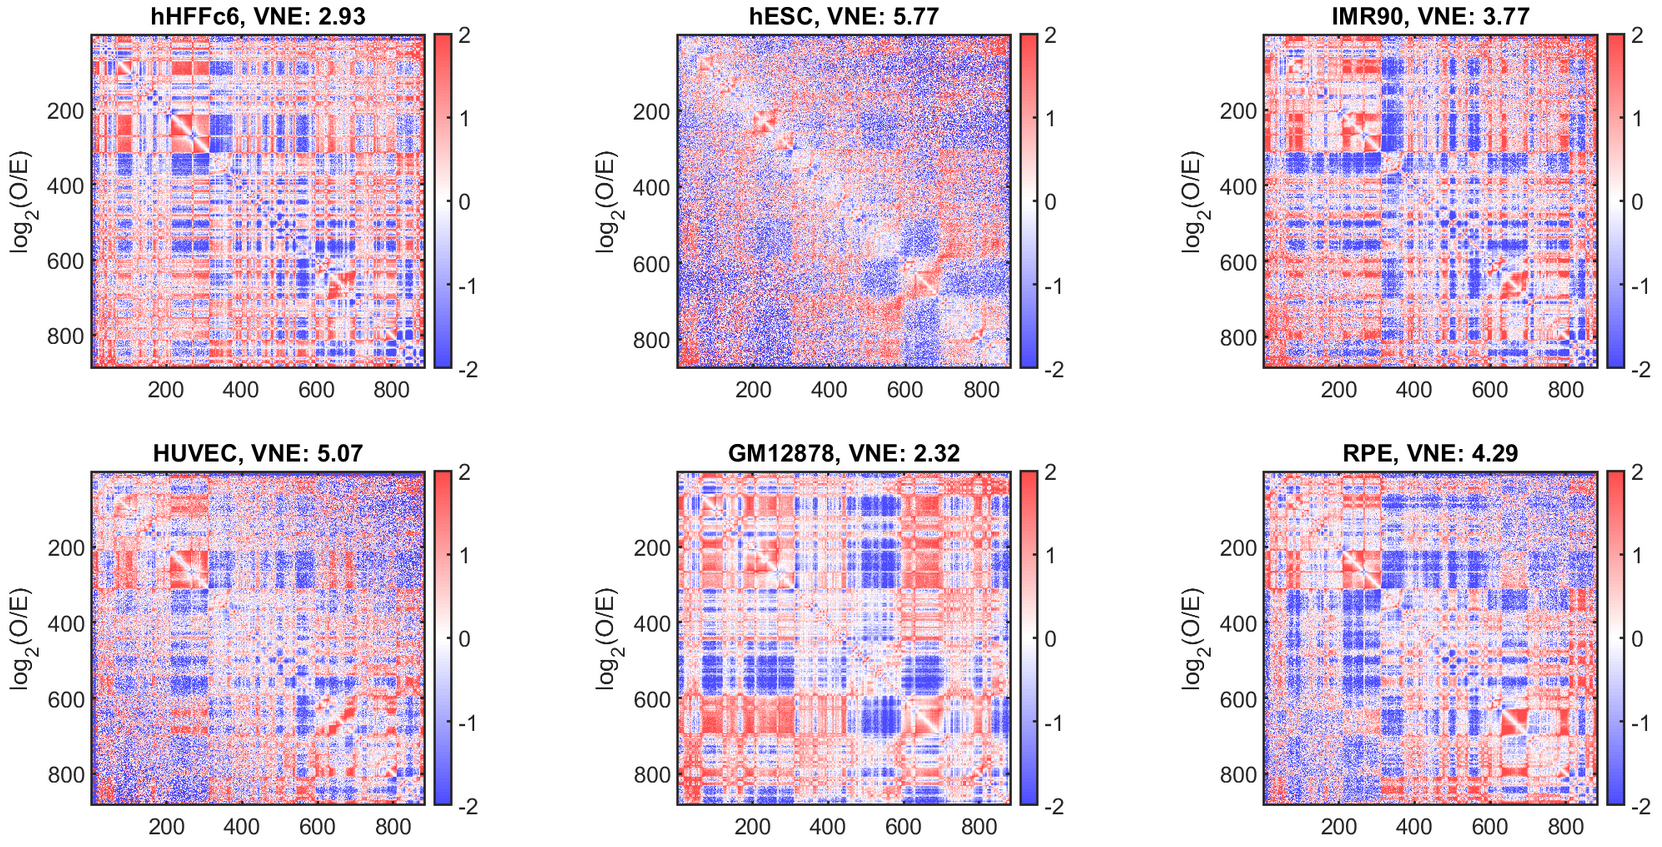

### Larntz-Perlman Method

The Larntz-Perlman (LP) method is used to compare Hi-C matrices from different cell types or time points. This is done by testing the equality of the Hi-C correlation matrices after a log2 transformation [5]. In this example, we show where a region of interest differs between three time points {-48, 8, 80 hours}. We recommend that the LP method is performed at Hi-C resolutions ≤ 100 kb and that regions do not extend > 5 Mb. The LP method calculates a *P*-value for the equality of Hi-C matrices and a matrix S, where the largest values in S correspond to genomic regions that are most different between samples.

The function **lpExample** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively. Within the function **lpExample**, the specific region of interest can be modified by the user.

Data_Loc = 'data\exampleData\myodData\myodData.mat'; %%% Data input
Folder_Result = 'results\lpExampleResults'; %%% Output folder

lpExample(Data_Loc, Folder_Result);

The LP method highlights where samples are most significantly different within a region of interest.  

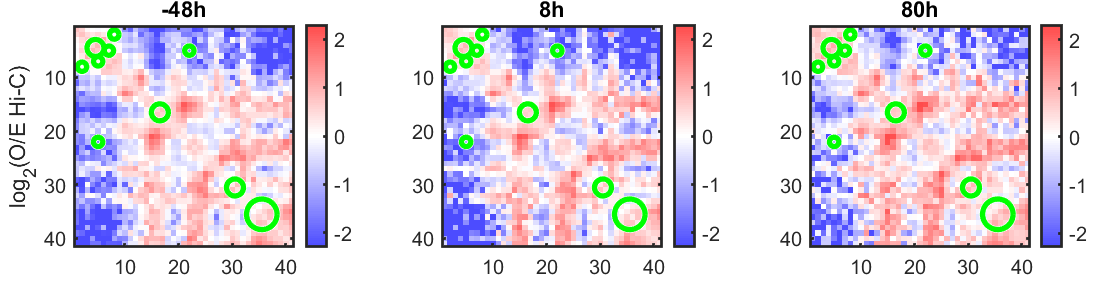

### Network Analysis

The 4DNvestigator enables us to model the dynamic genome structure as a multilayer network, where the inter-layers correspond to the snapshots of the network at different time points. Although nodal degree alone is an important network centrality measure, in a multilayer network, one needs to know the degree within a single layer as well as how the degree is distributed across different layers. In 4DNvestigator, we use the multiplex participation coefficient to evaluate the heterogeneity of nodal degrees in dynamic biological networks. Here we utilize overlapping degree and multiplex participation coefficient to understand the genome reorganization during the MYOD1-mediated fibroblast-to-muscle reprogramming process.

The function **networkExamples** requires the parameters **Data_Loc** and **Folder_Result** which denote the locations where the data can be accessed and the output figure is stored, respectively.

Data_Loc = 'data\exampleData\networkData\'; %%% Data input folder
Folder_Result = 'results\networkExamplesResults'; %%% Output folder

networkExamples(Data_Loc, Folder_Result);

The first outputs of **networkExamples **are two figures depicting overlapping degree versus multiplex participation coefficient for multilayer networks corresponding to time periods {0, 8, 16, 24 hours} and {32, 40, 48, 56 hours}, respectively. The top 5% of genes yielding the largest position shift before and after bifurcation are highlighted in the second figure (right). 

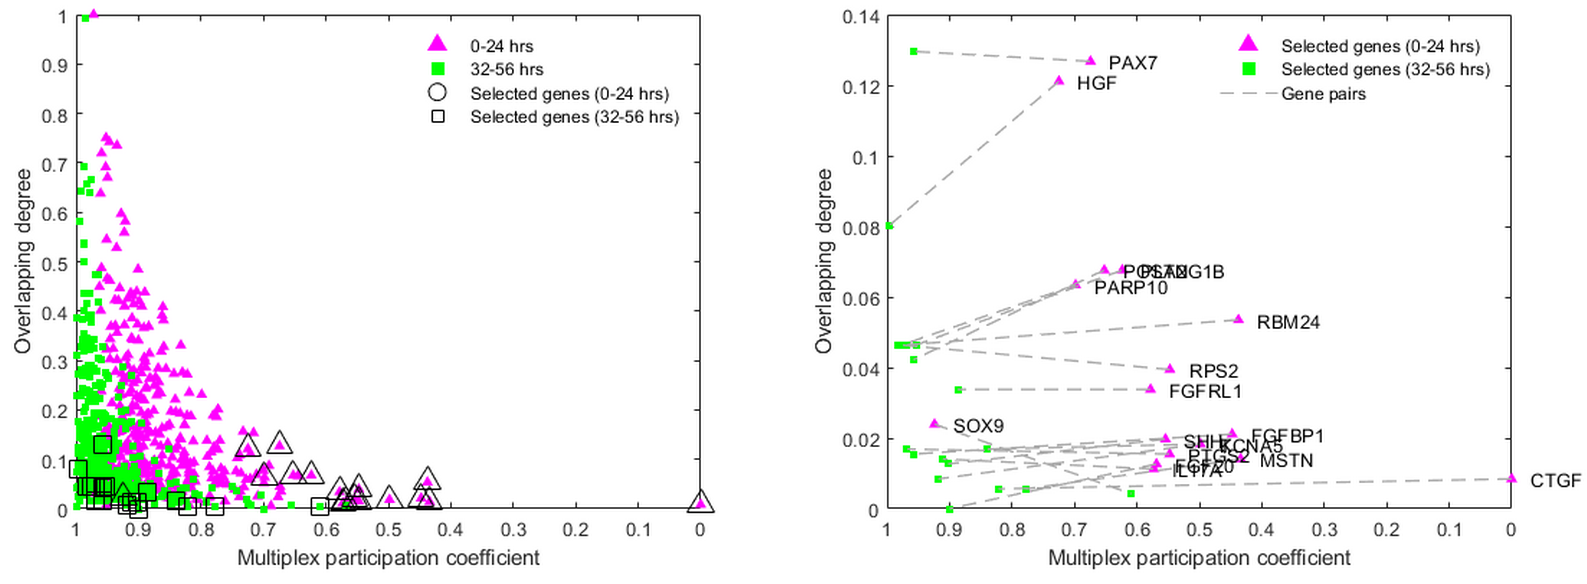

Next, **networkExamples** provides a network visualization of contact maps over 56 hours with highlighted genes *RPM24*, *CTGF*, and *FGFBP1*.

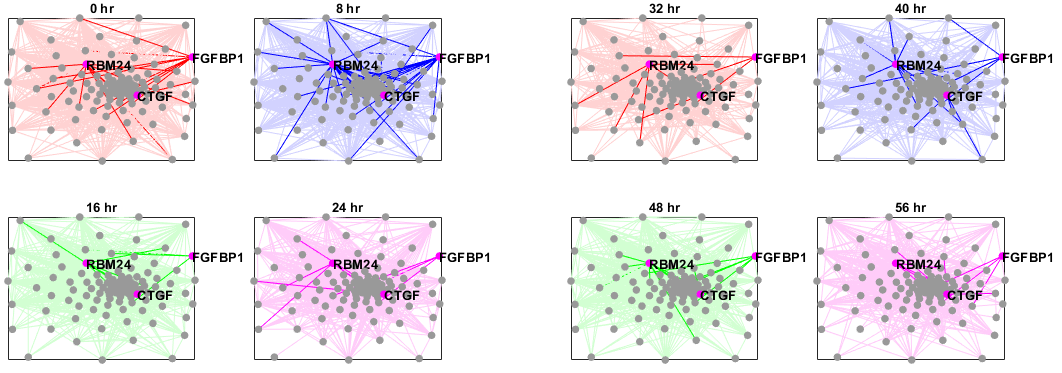

Finally, **networkExamples **summarizes intra- and inter-chromosome contacts of extracted genes in cellular reprogramming [1] versus fibroblast proliferation [6].

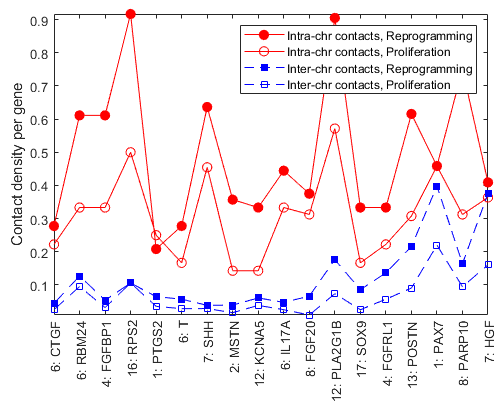

## Summary

The core functions of the 4DNvestigator offer multiple ways to study both gene expression and chromosome conformation over time. These functions can be easily adapted for other applications by changing their data input location. Through small modifications within each function, the 4DNvestigator can be used to study the genome as a whole, chromosomes, particular regions within chromosomes, or genes of interest. In addition, the 4DNvestigator contains many functions for more simple analyses including differential expression of genes and chromatin partitioning.

## References

- Liu, S., Chen, H., Ronquist, S., Seaman, L., Ceglia, N., Meixner, W., Chen, P.-Y., Higgins, G., Baldi, P., Smale, S., et al. (2018) Genome Architecture Mediates Transcriptional Control of Human Myogenic Reprogramming. iScience, 6

- Macarthur, B. D. and Lemischka, I. R. (2013) Statistical mechanics of pluripotency.Cell,154 (3),484–489.

- Rajapakse, I., Groudine, M., and Mesbahi, M. (2012) What can systems theory of networks offer to biology?. PLoS computational biology, 8 (6), e1002543.

- Meshorer, E. and Misteli, T. (2006) Chromatin in pluripotent embryonic stem cells and differentiation. Nature reviews Molecular cell biology, 7 (7), 540.

- Larntz, K. and Perlman, M. D. (1988) A simple test for equality of correlation matrices.Statistical Decision Theory and Related Topics IV, pp. 289–298.

- Chen, H., Chen, J., Muir, L. a., Ronquist, S., Meixner, W., Ljungman, M., Ried, T., Smale, S., and Rajapakse, I. (2015) Functional organization of the human 4D Nucleome. Proceedings  of  the  NationalAcademy of Sciences,112(26), 8002–8007.